## SVD in Data Analysis

The singular value decomposition is one of the key tools in data analysis.  It has many different uses, but we will focus on two: Data compression and dimensionality reduction.  

### Data Compression

Suppose that we have an $m\times n$ matrix $A$ with rank $k$.  That is, 

$A = \sigma_1\mathbf{u}_1\mathbf{v}_1^T + \sigma_2\mathbf{u}_2\mathbf{v}_2^T + \cdots + \sigma_k\mathbf{u}_k\mathbf{v}_k^T$.

If $k$ is fairly small compared to $m$ and $n$ (i.e., the matrix is not full rank), then this formula gives us a way to compress the matrix $A$.  That is, we can save space when storing the matrix.  This is because we can store the vectors $\mathbf{u}_i$ and $\mathbf{v}_i$ and the numbers $\sigma_i$ instead of the entire matrix $A$.  If $k$ (the rank of $A$) is small enough, then this ends up saving a pretty dramatic amount of space.  For example, suppose that $A$ is a $1,000,000\times 1,000,000$matrix, but it only has rank 10.  If we store the matrix directly, we need to save $1,000,000^2 = 1,000,000,000,000$ numbers.  This would require about eight terabytes of memory, which is impossible on any personal computer.  Instead, we can save the ten vectors $\mathbf{u}_i$, the ten vectors $\mathbf{v}_i$ and the ten numbers $\sigma_i$.  Each vector is $1,000,000\times 1$, so we only have to save $20,000,010$ numbers.  This only requires about 160 megabytes of memory, which is trivial on any modern computer.  The larger $A$ gets and the smaller $k$ gets, the more savings we get.  

Unfortunately, most of the large matrices one encounters in the real world are full rank.  This means that we can't immediately use the SVD to compress most matrices.  However, it turns out that a typical matrix $A$ usually has many extremely small singular values.  That is, none of the singular values are exactly zero, but most of them are very close to zero.  Since we always demand that the singular values be in descending order, this means that all but the first few singular values are often very small.  We already saw an example of this in the last lecture: We took a matrix that was supposed to have rank 2, but when we entered it into MATLAB we found that it had full rank (because of rounding error in MATLAB), but the last singular value was almost zero.  We can take advantage of this to approximate a full rank matrix by one that has low rank.  

Suppose that $A$ is an $m\times n$ matrix with $m \leq n$ and full rank (i.e., the rank of $A$ is $m$).  We can write our matrix as 

$A = \sigma_1\mathbf{u}_1\mathbf{v}_1^T + \sigma_2\mathbf{u}_2\mathbf{v}_2^T + \cdots + \sigma_m\mathbf{u}_m\mathbf{v}_m^T$.  

Now suppose that all but the first two singular values are extremely close to zero.  This means that all but the first two outer products in this equation are very small, so they don't contribute very much to the sum.  We can therefore approximate $A$ with the rank 2 matrix 

$A\approx A_{(2)} = \sigma_1\mathbf{u}_1\mathbf{v}_1^T + \sigma_2\mathbf{u}_2\mathbf{v}_2^T$.  

If $\sigma_3$, ..., $\sigma_m$ are small enough, then $A_{(2)}$ is very close to $A$.  This means that instead of storing the entire matrix $A$, we only need to store the first two singular vectors and values.  This saves a lot of space and still gives a good approximation of the full rank matrix.  

We call $A_{(2)}$ a rank 2 approximation of $A$, and in general we use this approach to find *low rank approximations* of $A$.  It is possible (although somewhat difficult) to prove that this method produces the *best* low rank approximations of $A$.  That is, if you set all but the first $k$ singular values to zero, then the resulting matrix $A_{(k)}$ is the rank $k$ matrix whose entries are as close as possible to the entries of $A$.  (Just like when we discussed data fitting, the notion of a "best approximation" is intimately related to how we define "close to".  Instead of the RMS error, this theorem uses something called the *Frobenius norm* to measure the distance between two matrices.  For this class, you don't need to worry about these details, but it is always good to keep such ideas in mind when you hear a mathematician talk about "best".)

To see this in action, consider the data in the file `large_dataset.csv`.  

data = load('large_dataset.csv');
[m, n] = size(data)

m = 4032

n = 3024

This is a $4032\times 3024$ matrix, which takes about 97.5 Mb of memory to store.  We can find the (reduced) singular value decomposition of this matrix with the code 

[U, S, V] = svd(data, 'econ');

Notice that U is $4032\times 3024$ and S is $3024\times 3024$ and V is $3024\times 3024$.  U is not square because we are using the reduced SVD.  The singluar values of our data matrix are on the diagonal of S.  We can visualize them with a plot: 

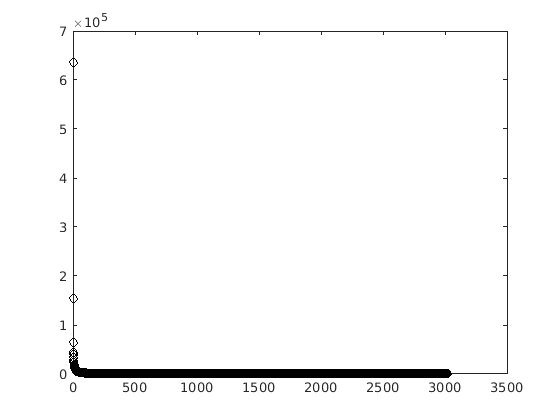

s = diag(S);
plot(s, 'ko')

This is incrediby hard to read because most of the singular values are a lot smaller than the first few.  (None of them are zero, however.  The smallest singular value is 

s(end)

ans = 1.2428

It will be easier to see what's going on if we focus on the first 100 values.

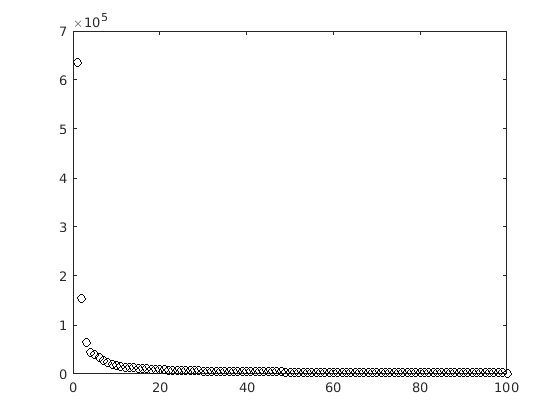

plot(s(1:100), 'ko')

This graph suggests that the first handful of singular values might be contributing a lot more to the sum


$$\textrm{data} = \sigma_1\mathbf{u}_1\mathbf{v}_1^T + \sigma_2\mathbf{u}_2\mathbf{v}_2^T + \cdots + \sigma_n\mathbf{u}_n\mathbf{v}_n^T$$


than any of the other values, and so we could set the latter singular values to zero and still get a good low rank approximation to our data matrix.  

#### Energy

We can quantify this a little more precisely with something known as the *energy* of our approximation.  In this context, the energy of a matrix is the sum of the squares of its singular values, and so the energy of the rank $k$ approximation of a matrix is the sum of the first $k$ singular values: 


$$E_k = \sum_{i=1}^{k}\sigma_i^2.$$


The absolute scale of these energy values is not usually relevant, and so it is common to divide each $E_k$ by the total energy of the original matrix.  That is, to find $E_k / E_n$.  We can find these energies with the `cumsum` command.  

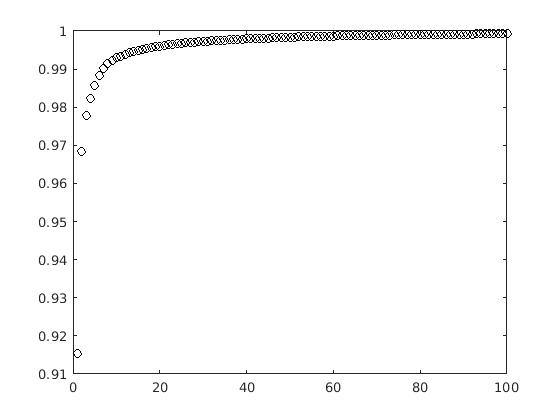

E = cumsum(s.^2) / sum(s.^2);
plot(E(1:100), 'ko')

Because we divided by $E_n$, these values are always between 0 and 1.  We can interpret this value $E_k/E_n$ as the percentage of information from the original matrix contained in the rank $k$ approximation.  (I am being deliberately vague here.  If you take a statistics or data analysis class, you will learn when and how you can interpret these energies in terms of the variance in your data, but we will just be sloppy and think of this as "amount of information".)  If we replace our matrix `data` with a rank 10 approximation, then we will retain 

E(10)

ans = 0.9929

roughly 99.29% of the information from the orignal data.  If we instead use a rank 100 approximation, we will retain roughly 

E(100)

ans = 0.9993

99.93% of the information from the original data.  If we instead use a rank 500 approximation, we will retain roughly 

E(500)

ans = 1.0000

99.995% of the information from the original data.  Of course, the only way to retain all of the information would be to use all 3024 singular values.  

How much memory could we save by using these low rank approximations?  The original matrix takes 

total_mem = m * n * 8 / 1000000

total_mem = 97.5421

megabytes of memory.  (The 8 / 1000000 is the number of megabytes required to store one number.)  If we instead just store the first 500 singular values and vectors, we only need 

rank500_mem = 500 * (m + n + 1) * 8 / 1000000

rank500_mem = 28.2280

If we only use the first 100 singular values and vectors, we only need 

rank100_mem = 100 * (m + n + 1) * 8 / 1000000

rank100_mem = 5.6456

megabytes of memory, and if we only use the first 10 then we only need 

rank10_mem = 10 * (m + n + 1) * 8 / 1000000

rank10_mem = 0.5646

megabytes.  

These are all pretty substantial savings, especially if we get our matrix 99.9% correct.  However, it isn't obvious from our definitions that "retaining 99.9% of the information in our matrix" is particularly meaningful.  Is 99.9% a good number?  Is 99.29% a good number?  Could we get away with only 50%?  To a large extent, this just depends on where the data came from and what you are using it for.  

In this case, our data is actually a photograph.  Every entry in the matrix `data` encodes the grayscale value of one pixel (where 0 means black, 255 means white, and values in between are shades of gray).  We can see this picture with the code 

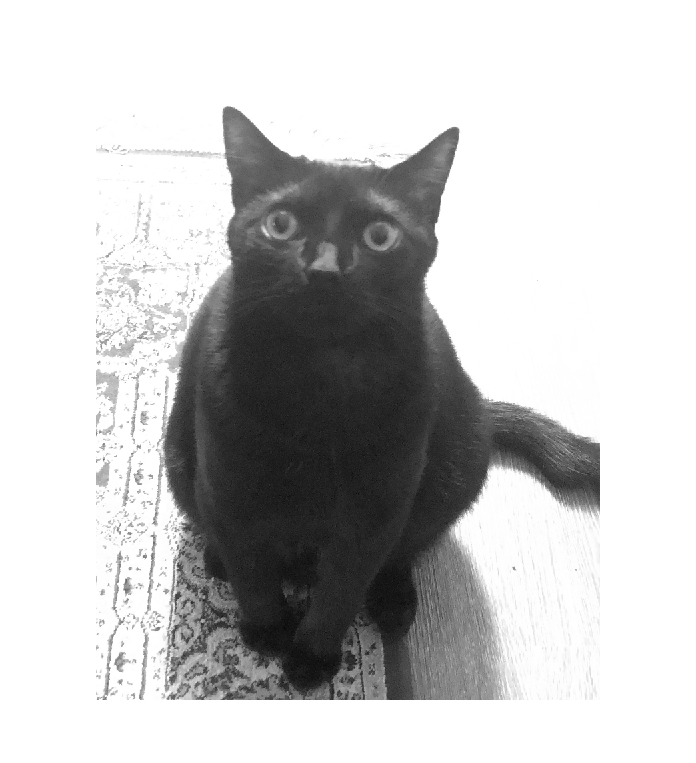

imshow(data, [])

To test the quality of our compressed data sets, let's use the same code to look at several different low rank approximations of the photograph.  (The "subplot" command below is just to make the images show up in a grid instead of one after the other.)

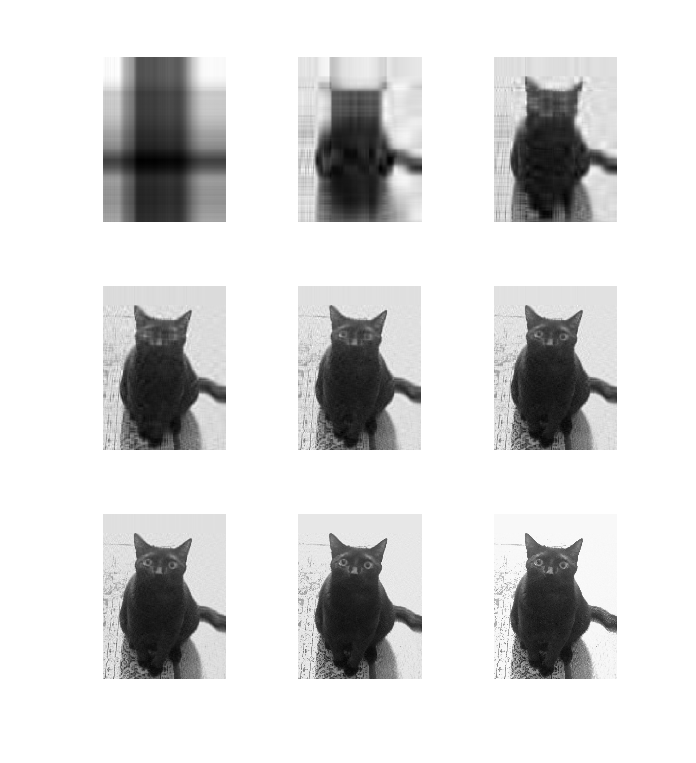

ranks = [1, 5, 10, 20, 30, 40, 50, 100, 500];
for i = 1:length(ranks)
    k = ranks(i);
    % Throw away all but the first k columns of U and V and all but the
    % first k singular values
    Uk = U(:, 1:k);
    Vk = V(:, 1:k);
    Sk = diag(s(1:k));
    % Reconstruct the data with these smaller versions of U, V and S
    reconstructed_data = Uk * Sk * Vk';
    % Display the image in a grid
    subplot(3, 3, i)
    imshow(reconstructed_data, [])
end

Around rank 10 (the top right image), it becomes clear that there is a cat in the picture.  Around rank 40 or 50 (the middle right or bottom left image), the reconstructed image becomes essentially indistinguishable from the original.  If we used the rank 50 approximation instead of the original photo, we could store it with only 

rank50_mem = 50 * (m + n + 1) * 8 / 1000000

rank50_mem = 2.8228

megabytes of memory.  This approximation captures almost all of the information in our image, because 

E(k)

ans = 1.0000

is almost exactly 1.  (It's not exactly 1, but the first four decimal places round up to 1.)  

### Dimensionality Reduction

Another important use of the SVD is to reduce the dimensionality of a data set.  To understand what this means, let's look at an example.  Suppose that I have a weight attached to a spring hanging from the ceiling and I pull the weight down and then release it.  The spring will bounce up and down and gradually come to a stop, and it will probably also wobble a bit from side to side (because I didn't pull it exactly straight or because the spring is not completely symmetrical).  Now suppose that I arrange several cameras around this spring.  Each can sense the position of the weight at any given time and report the position as an $(x, y, z)$ value, but the cameras are all oriented differently and don't agree on which direction is up (the positive $z$ direction) or right (the positive $x$ direction) or into the frame (the positive $y$ direction).  In addition, none of the cameras are perfectly still, and so the $x$, $y$ and $z$ values all have some small errors.  We would like to be able to look at the data from this camera and (without any knowledge of where the data came from or the fact that there was a spring involved) determine that all ten cameras were watching the same object, and that that object was mostly just moving back and forth in one direction.  

The file `pendulum.csv` contains data from just such an experiment.  

data = readmatrix('pendulum.csv');
[m, n] = size(data)

m = 30

n = 101

Each row of this matrix corresponds to the $x$, $y$ or $z$ data from one camera.  The rows are grouped by camera, so the first three rows are from camera 1, the next three are from camera 2, etc.  As an example, the third camera sees the following data: 

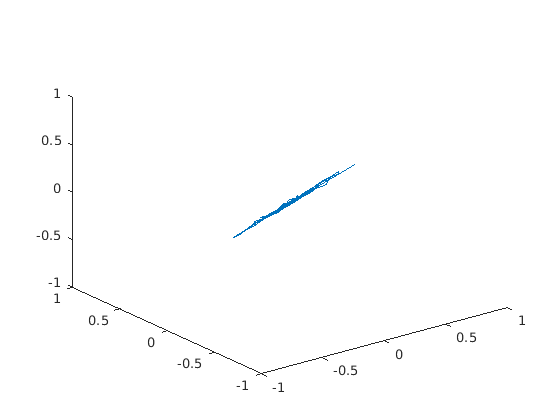

x = data(7, :);
y = data(8, :);
z = data(9, :);
plot3(x, y, z)
xlim([-1 1])
ylim([-1 1])
zlim([-1 1])

As you can see, the positions recorded by the camera lie roughly on a straight line, but the line is not vertical.  Every camera looks similar, but the line points in a different direction.  

We know where this data came from, and so we know that all ten cameras are reporting the movement of the same object, but how could we determine that from the data?  In other words, we currently have a 30-dimensional data set, because we have $x$, $y$ and $z$ directions from ten different cameras, but the underlying dynamics are really just 1-dimensional, because there is one object moving mostly up and down.  

To better understand our data, we can find the SVD of the data matrix: 

[U, S, V] = svd(data, 'econ');

Notice the dimensions.  Because we used the reduced SVD, we got a $30\times 30$ matrix U, a $30\times 30$ matrix S and a $101\times 30$ matrix V.  

Let's look at the singular values.  

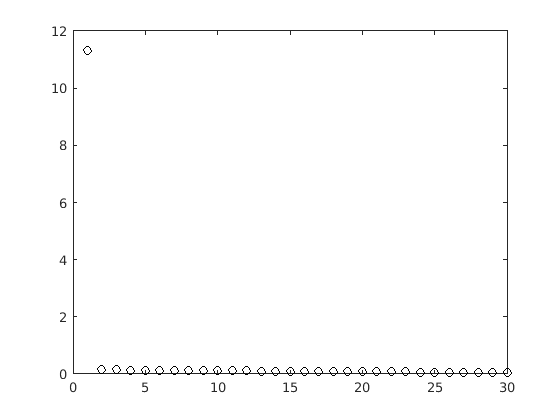

s = diag(S);
plot(s, 'ko')

It's pretty clear that one of the singular values is much bigger than the others.  We can quantify this by calculating the (scaled) energies: 

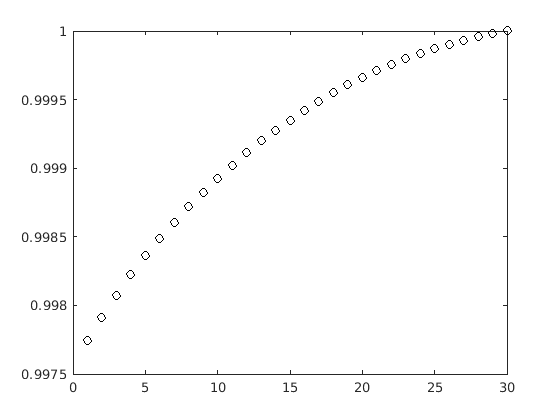

E = cumsum(s.^2) / sum(s.^2);
plot(E, 'ko')

E(1)

ans = 0.9977

Notice the scale on the $y$-axis.  The rank 1 approximation of this data set accounts for 99.77% of the information in the data set.  This means that our data is very close to being rank 1 (even though it is technically full rank, because none of the singular values are exactly 0).  This information tells us that the data are essentially one dimensional.  

The columns of V are called the *principal directions* of our data set.  They are also often called eigenvectors.  (This is confusing terminology, because they are not the eigenvectors of the matrix `data`, but they are the eigenvectors of a related matrix.  We will just call them principal directions for now.)  Since the first singular value accounts for 99.77% of the energy in our matrix, we know that the first principal direction (i.e., the first column of V) is by far the most important.  What does this vector look like?  

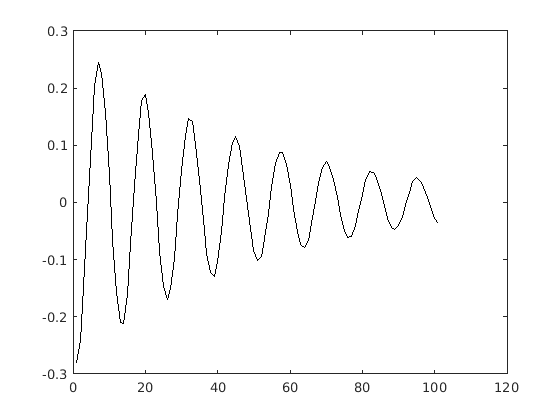

plot(V(:, 1), 'k')

This is exactly what we wanted!  We found that our data was approximately one dimensional (because the first singular value accounted for almost all the energy of our matrix) and the data along that direction moved in a decaying oscillation.  This is exactly the graph one would expect from the motion of a spring bouncing up and down.  (It's worth noting that the scale of the $y$-axis doesn't give you any information about the original data.  The `svd` function scales the columns of `V` so that they are all length 1, and so the height of these oscillations is arbitrary, but the shape is extremely important.  

Since the other singular values are very small, we should expect that the other principal directions do not contain any useful information.  For instance, if we plot the second principal direction we see

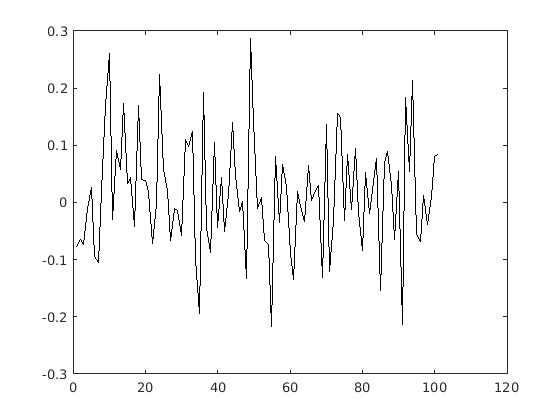

plot(V(:, 2), 'k')

There is no obvious pattern here.  This is just noise from the movement of the cameras or wobbling in the spring.  